% 读取数据
filename = 'D:\Drivers\CarbonEmissiondata\Liaoning_data.xlsx'; 
dataTable = readtable(filename);

% 提取碳排放数据
dataCE = dataTable.CarbonEmissions_mt(1:25);
years = dataTable.Year(1:25);

% 插值处理
missingIndex = isnan(dataCE);
dataCE(missingIndex) = interp1(years(~missingIndex), dataCE(~missingIndex), years(missingIndex), 'spline');

% 构建时间序列数据
carbonEmissionsTS = timeseries(dataCE, years);

% 拟合ARIMA模型
model = arima(3,1,2); % 尝试不同参数组合以找到最佳模型
fit = estimate(model, carbonEmissionsTS.Data);

 
    ARIMA(3,1,2) Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________    __________

    Constant      2.304        1.3672         1.6852        0.091951
    AR{1}        1.7393       0.44496          3.909      9.2691e-05
    AR{2}       -1.0475       0.58711        -1.7841        0.074405
    AR{3}       0.16377       0.23521        0.69628         0.48625
    MA{1}            -2       0.26668        -7.4995      6.4066e-14
    MA{2}             1       0.37298         2.6811        0.007338
    Variance     216.83        91.449          2.371         0.01774



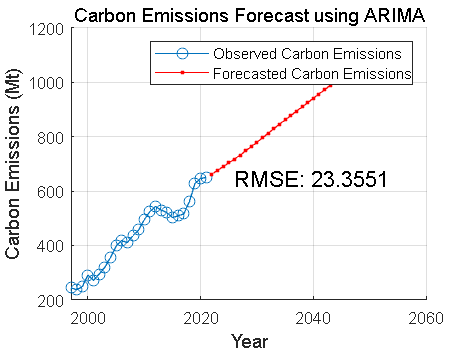


% 预测未来28年碳排放量
numYearsToPredict = 28;
[YPred, YMSE] = forecast(fit, numYearsToPredict, 'Y0', carbonEmissionsTS.Data);

% 计算RMSE
RMSE = sqrt(mean(YMSE));

% 预测结果的年份
futureYears = (years(end)+1):(years(end)+numYearsToPredict);

% 画图
figure;
hold on;
plot(years, dataCE, '-o', 'DisplayName', 'Observed Carbon Emissions');
plot(futureYears, YPred, 'r.-', 'DisplayName', 'Forecasted Carbon Emissions');
hold off;

xlabel('Year');
ylabel('Carbon Emissions (Mt)');
title('Carbon Emissions Forecast using ARIMA');
legend show;
grid on;

% 添加RMSE值到图表
text(years(end)+5, max(dataCE)-5, ['RMSE: ', num2str(RMSE)], 'Color', 'k', 'FontSize', 12);


% 保存预测结果
%writematrix([futureYears' YPred], 'D:\Drivers\ARIMA_CarbonEmission_Predictions.xlsx');

% 输出预测结果
disp('Predicted Carbon Emissions:');

Predicted Carbon Emissions:


disp([futureYears' YPred]);

   1.0e+03 *

    2.0220    0.6623
    2.0230    0.6760
    2.0240    0.6897
    2.0250    0.7034
    2.0260    0.7175
    2.0270    0.7322
    2.0280    0.7475
    2.0290    0.7634
    2.0300    0.7797
    2.0310    0.7962
    2.0320    0.8128
    2.0330    0.8293
    2.0340    0.8456
    2.0350    0.8617
    2.0360    0.8777
    2.0370    0.8936
    2.0380    0.9094
    2.0390    0.9252
    2.0400    0.9410
    2.0410    0.9569
    2.0420    0.9728
    2.0430    0.9887
    2.0440    1.0047
    2.0450    1.0207
    2.0460    1.0367
    2.0470    1.0527
    2.0480    1.0687
    2.0490    1.0847



disp(['RMSE: ', num2str(RMSE)]);

RMSE: 23.3551
